clear all;
close all;
clc;

# StanDep thresholding reactions

This code is designed to execute the global thresholding algorithm. Created by Pablo Tejero during his internship at MaCSBio.

It is necessary to use COBRAToolbox, a MATLAB toolbox specifically for metabolic network analysis and model reconstruction. The Gurobi solver is also used, although MATLAB's built-in solver can be used.

## Gurobi setup and Cobra Toolbox initialization

The Gurobi solver is initialised, as well as COBRAToolbox.

initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.45.2).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.


 > TranslateSBML is installed and working properly.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] GUROBI_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ...Gurobi installed at this location? 
Licence file current? 


changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Original LP has 1 row, 2 columns, 1 non-zero
Objective value = 0
OPTIMAL SOLUTION FOUND BY LP PRESOLVER

 > [glpk] Primal optimality condition in solveCobraLP satisfied.Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle 

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    0 	    0 	    0 	    0 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek    

## Load data

- Gene expression data.

- Housekeeping gene lists: both Eisenberg and Housekeeping Atlas lists one.

- Housekeeping enzymes: Calculated based on the AND rules of the Genome-Scale Metabolic Model.

- Model: Genome-Scale Metaoblic Model, Human1 v1.17 is used in this project. 

cd('C:/Users/pablo/OneDrive/Documentos/Systems_Biology_master/Github_folder/Internship/Data');
data = readtable("data_TPM.xlsx");

% Eisenberg list
h_k_g = readtable('NM2ENSG.xlsx');

% HKAtlas list
hk_gene_new = readtable('ENS_ID_HKG.xlsx');
hk_gene_new = table2cell(hk_gene_new);

% Joshi list
test_HKG = readtable('journal.pcbi.1010295.s014.xlsx', 'Sheet','Human');
test_HKG = table2cell(test_HKG);

% Genome-Scale Metabolic Models
model = load('SysBio_COBRA_v1.17_consensus.mat'); % Human1 metabolic model
model = model.myModel;
% model_Alicia = load('SysBio_COBRA_v1.17_consensus1.mat');
% model_Alicia = model_Alicia.myModel;

## Ensure the model does not contain blocked reactions

The Genome-Scale Metabolic model may contain blocked reactions, which could affect further analysis. A pruned model is obtained using findFluxConstentSubset function from COBRATolbox. 

%[fluxConsistentMetBool, fluxConsistentRxnBool, fluxInConsistentMetBool, fluxInConsistentRxnBool, ~, fluxConsistModel] = findFluxConsistentSubset(model);
%model_p = fluxConsistModel; % load the new model with no blocked reactions
%save('model_p.mat', 'model');
model_p = load('model_p.mat');
model_p = model_p.model_p;
model_genes_p = model_p.genes; % ENSEMBL_IDs of the genes in the model
%model_genes = model.genes;
cd('C:/Users/pablo/OneDrive/Documentos/Systems_Biology_master/Github_folder/Internship/Thresholding/StanDep');

## Preprocessing

Expression data should be normalized to make the interpretation easier. A new matrix is created, including a first column called 'gene' including the ENSEMBL_IDs, and one column for each sample. The fene expression data is normalized based on this equation:

*normalized_data = log10(data + 1)*

The 1 is added to avoid obtaining -inf values (log10(0)) that can affect the results. Those normalized values are added to their correspondent genes and samples. The normalized table is created. 

% Colect the data needed to create the table
Ensembl_id = data(:, 1);
NamesSample = data.Properties.VariableNames(2:end); 
data_to_log = table2array(data(:, 2:end));
logged_data = log10(data_to_log + 1); 

%Create the new table with the data obtained before
log_data = [Ensembl_id, array2table(logged_data)]; % Load the data on the new table  
log_data.Properties.VariableNames(2:end) = NamesSample; % Variables names 
log_data.Properties.VariableNames{1} = 'gene'; % Change ENSEML_ID name to gene (To run findUsedGenesLevels)

## Processing the Genome-Scale Metabolic Models

Metabolic gene expression is extracted based on both, pruned and unpruned model. Those two matrices will be used afterwards.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% PRUNED MODEL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
geneExpressionMatrix_P = [];

for i = 1: width(NamesSample)
    log_data.value = log_data{:, i + 1}; %- min(log_data{:, i + 1}); % shift minimum to 0 ¡¡ ASK MARIAN HOW HE WANT TO NORMALIZE IT!! ACTUALLY IT SAYS FPKM, SO I ALREADY HAVE IT
    [geneList, geneExpression] = findUsedGenesLevels(model_p, log_data); % Athough is just for the last sample, the genes present in the models are always the same
    geneExpressionMatrix_P = [geneExpressionMatrix_P, geneExpression'];
    log_data.value = [];
end

% Convert the results into a table
metabolic_genes_P = array2table(geneExpressionMatrix_P, 'RowNames', geneList, 'VariableNames', NamesSample);
% Delete the NaN values
metabolic_genes_P = rmmissing(metabolic_genes_P, 'MinNumMissing', size(metabolic_genes_P, 2)); % So we can use the local thresholding 
% metabolic genes pruned extra column with the means
sampleNames = metabolic_genes_P.Properties.VariableNames;

## StanDep

Change the name of the column that contains the Ensembl_ID to gene, and normalize the data, ACTUALLY IT IS ALREADY NORMALIZED, SO NO NEEDED. ASK THIS

%Ensuring that the first colum is names 'gene' 
data_met = metabolic_genes_P;
data_met.gene = data_met.Properties.RowNames;
columnNames = ['gene', data_met.Properties.VariableNames];
data_met = data_met(:, columnNames);
data_met.gene_1 = [];
data_met.Properties.RowNames = {};
%Although this is not documented clearly, standep will perform a log10 on
%the expression data. To ensure that this does not introduce negative
%numbers we add 1 everywhere.
datalog10 = data_met;
%datalog10{:,2:end} = datalog10{:, 2:end};%(datalog10{:,2:end}+1)

Define the limits of the bins:

%Standep requires us to define the bin boundaries. IMPORTANTLY these
%boundaries have to be in a log scale...
maxlog10 = max(max(table2array(datalog10(:,2:end))));
edgeX = linspace(0,maxlog10,11); %If we want 10 bins we need 11 
edgeX = round(edgeX,1); %These are our bin bounds!

Pre-processing of the data for Standep

%Standep requires a very specific pre-processing for the inputs!
%1st, the RNA data structure
rnaData = struct();
rnaData.gene = data_met.gene;
rnaData.value = table2array(data_met(:,2:end));
rnaData.valuebyTissue = table2array(data_met(:,2:end));
rnaData.Tissue = data_met.Properties.VariableNames(2:end)';

Pre-processing of the metabolic model

%2nd the model data structure
modelData = getModelData(rnaData,model_p);

Pre-processing of the enzyme data 

%3rd the enzyme data structure
spec = getSpecialistEnzymes(model_p);  
prom = getPromEnzymes(model_p);
enzymeData = comparePromiscuousSpecific(spec,prom,modelData);

Set the parameters for the clustering analysis

% We then set our parameters...
distMethod = 'euclidean'; % distance method  maybe think one more robust than euclidean.
linkageMethod = 'complete'; % linkage metric for hierarchical clustering
k = 10;

Clustering analysis

Cophenetic correlation coeffcient using complete linkage and euclidean distance = 0.9477


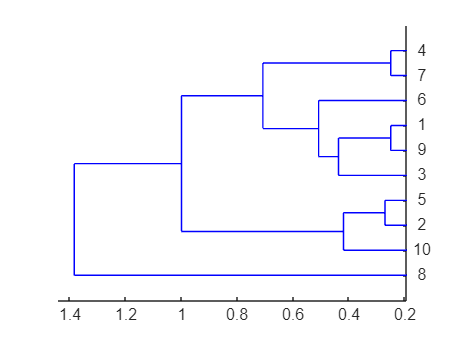

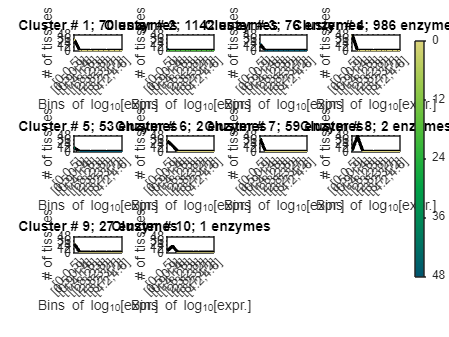

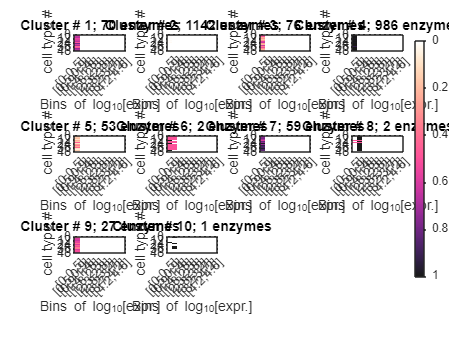

clustObj = struct with fields:
     Distribution: [2418×10 double]
          numObjs: [2418×1 double]
          objects: {2418×1 cell}
       objectMaps: {2418×1 cell}
                C: [10×10 double]
           cindex: [2418×1 double]
             Data: [2418×48 double]
    numObjInClust: [10×1 double]


close all %This is important to ensure that all standep plots have the right number to be saved if we wish
clustObj = geneExprDist_hierarchy(enzymeData,[],edgeX,k,distMethod,linkageMethod)

Identify core reactions and calculate ubiquity score?

[coreRxnMat,enzTis,cutOff,thr] = models4mClusters1(clustObj,enzymeData.Tissue,model_p,edgeX,[],[],false,0,[1 1]); %CoreRxnMat defines the core set of reactions in a general sense

Top 25th percentile for the data = 0.2038
Mean of Data = -0.2683
Std. Dev. of Data = 0.1887
fraction selected = 0.9988
fraction selected = 0.0000
fraction selected = 0.9981
fraction selected = 1.0000
fraction selected = 0.0004
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 0.9985
fraction selected = 0.0208


[ubiScore,uScore] = getUbiquityScore_2022(clustObj,edgeX,model_p); %ubiScore is the ubiquity score per rxns to use in mCadre!

Top 25th percentile for the data = 0.2038
Mean of Data = -0.2683
Std. Dev. of Data = 0.1887


## CREATE Context-Specific Model with FASTCORE

% % Select the indices of reactions where the ubiquity score in the specified column is 1
% coreRxnIndices = find(ubiScore(:, 12) == 1);
% 
% % Retrieve the reaction names corresponding to these indices
% coreRxnNamesSelected = model_p.rxns(coreRxnIndices);
% 
% % Parameters for fastcore (optional)
% % epsilon = 1e-1;
% % printLevel = 2;
% 
% % Call the fastcore function with the indices of the core reactions
% FASTCORE_MEAN_SD = fastcore(model_p, coreRxnIndices); % , epsilon, printLevel);
% save('FASTCORE_IMR90_O3_SD.mat', 'FASTCORE_MEAN_SD');
ubiquityScore = ubiScore(:,1);
confidenceScore = zeros(size(ubiquityScore));
protectedRxns = [];
checkFunctionality = 0;
eta = 1/3;
tol = 1e-8;
extractedModel = mCADRE(model_p,ubiquityScore,confidenceScore, protectedRxns,checkFunctionality,eta,tol);

Processing inputs and ranking reactions...
Generic model passed precursor metabolites test
Pruning reactions...
Reaction no. 1
Attempting to remove reaction MAR00015...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6719

Reaction no. 2
Attempting to remove reaction MAR00016...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6718

Reaction no. 3
Attempting to remove reaction MAR00012...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6717

Reaction no. 4
Attempting to remove reaction MAR10033...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6716

Reaction no. 5
Attempting to remove reaction MAR03248...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6715

Reaction no. 6
Attempting to remove reaction MAR00035...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6714

Reaction no. 7
Attempting to remove reaction MAR00014...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6713

Reaction no. 8
Attempting to remove reaction MAR00017...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6712

Reaction no. 9
Attempting to remove reaction MAR00013...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6711

Reaction no. 10
Attempting to remove reaction MAR00477...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6710

Reaction no. 11
Attempting to remove reaction MAR00036...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6709

Reaction no. 12
Attempting to remove reaction MAR06869...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6708

Reaction no. 13
Attempting to remove reaction MAR07439...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6707

Reaction no. 14
Attempting to remove reaction MAR10063...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6706

Reaction no. 15
Attempting to remove reaction MAR06867...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6705

Reaction no. 16
Attempting to remove reaction MAR06920...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6704

Reaction no. 17
Attempting to remove reaction MAR07195...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6703

Reaction no. 18
Attempting to remove reaction MAR06922...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6702

Reaction no. 19
Attempting to remove reaction MAR07255...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6701

Reaction no. 20
Attempting to remove reaction MAR06868...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6700

Reaction no. 21
Attempting to remove reaction MAR06919...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6699

Reaction no. 22
Attempting to remove reaction MAR09022...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6698

Reaction no. 23
Attempting to remove reaction MAR02643...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6697

Reaction no. 24
Attempting to remove reaction MAR00008...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6696

Reaction no. 25
Attempting to remove reaction MAR07159...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6695

Reaction no. 26
Attempting to remove reaction MAR02639...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6694

Reaction no. 27
Attempting to remove reaction MAR02641...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6693

Reaction no. 28
Attempting to remove reaction MAR12861...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6692

Reaction no. 29
Attempting to remove reaction MAR12863...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6691

Reaction no. 30
Attempting to remove reaction MAR07176...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6690

Reaction no. 31
Attempting to remove reaction MAR11292...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6689

Reaction no. 32
Attempting to remove reaction MAR01056...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6688

Reaction no. 33
Attempting to remove reaction MAR01076...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6687

Reaction no. 34
Attempting to remove reaction MAR01856...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6686

Reaction no. 35
Attempting to remove reaction MAR07961...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6685

Reaction no. 36
Attempting to remove reaction MAR07994...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6684

Reaction no. 37
Attempting to remove reaction MAR08002...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6683

Reaction no. 38
Attempting to remove reaction MAR08057...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6682

Reaction no. 39
Attempting to remove reaction MAR08061...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6681

Reaction no. 40
Attempting to remove reaction MAR08154...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6680

Reaction no. 41
Attempting to remove reaction MAR08158...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6679

Reaction no. 42
Attempting to remove reaction MAR08161...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6678

Reaction no. 43
Attempting to remove reaction MAR08164...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6677

Reaction no. 44
Attempting to remove reaction MAR08223...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6676

Reaction no. 45
Attempting to remove reaction MAR08253...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6675

Reaction no. 46
Attempting to remove reaction MAR08270...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6674

Reaction no. 47
Attempting to remove reaction MAR08283...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6673

Reaction no. 48
Attempting to remove reaction MAR08304...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6672

Reaction no. 49
Attempting to remove reaction MAR08311...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6671

Reaction no. 50
Attempting to remove reaction MAR08313...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6670

Reaction no. 51
Attempting to remove reaction MAR08315...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6669

Reaction no. 52
Attempting to remove reaction MAR08321...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6668

Reaction no. 53
Attempting to remove reaction MAR08324...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6667

Reaction no. 54
Attempting to remove reaction MAR08714...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6666

Reaction no. 55
Attempting to remove reaction MAR08881...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6665

Reaction no. 56
Attempting to remove reaction MAR08896...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6664

Reaction no. 57
Attempting to remove reaction MAR08898...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6663

Reaction no. 58
Attempting to remove reaction MAR09182...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6662

Reaction no. 59
Attempting to remove reaction MAR09648...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6661

Reaction no. 60
Attempting to remove reaction MAR09653...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6660

Reaction no. 61
Attempting to remove reaction MAR09654...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6659

Reaction no. 62
Attempting to remove reaction MAR09655...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6658

Reaction no. 63
Attempting to remove reaction MAR09658...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6657

Reaction no. 64
Attempting to remove reaction MAR09663...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6656

Reaction no. 65
Attempting to remove reaction MAR09993...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6655

Reaction no. 66
Attempting to remove reaction MAR09995...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6654

Reaction no. 67
Attempting to remove reaction MAR10000...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6653

Reaction no. 68
Attempting to remove reaction MAR10414...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6652

Reaction no. 69
Attempting to remove reaction MAR10418...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6651

Reaction no. 70
Attempting to remove reaction MAR10421...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6650

Reaction no. 71
Attempting to remove reaction MAR11227...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6649

Reaction no. 72
Attempting to remove reaction MAR11228...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6648

Reaction no. 73
Attempting to remove reaction MAR11229...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6647

Reaction no. 74
Attempting to remove reaction MAR11230...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6646

Reaction no. 75
Attempting to remove reaction MAR11231...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6645

Reaction no. 76
Attempting to remove reaction MAR11232...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6644

Reaction no. 77
Attempting to remove reaction MAR11298...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6643

Reaction no. 78
Attempting to remove reaction MAR11460...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6642

Reaction no. 79
Attempting to remove reaction MAR11472...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6641

Reaction no. 80
Attempting to remove reaction MAR11484...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6640

Reaction no. 81
Attempting to remove reaction MAR11504...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6639

Reaction no. 82
Attempting to remove reaction MAR11511...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6638

Reaction no. 83
Attempting to remove reaction MAR11523...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6637

Reaction no. 84
Attempting to remove reaction MAR11527...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6636

Reaction no. 85
Attempting to remove reaction MAR11532...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6635

Reaction no. 86
Attempting to remove reaction MAR11537...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6634

Reaction no. 87
Attempting to remove reaction MAR11542...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6633

Reaction no. 88
Attempting to remove reaction MAR11567...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6632

Reaction no. 89
Attempting to remove reaction MAR11817...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6631

Reaction no. 90
Attempting to remove reaction MAR11820...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6630

Reaction no. 91
Attempting to remove reaction MAR11846...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6629

Reaction no. 92
Attempting to remove reaction MAR11979...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6628

Reaction no. 93
Attempting to remove reaction MAR12332...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6627

Reaction no. 94
Attempting to remove reaction MAR12336...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6626

Reaction no. 95
Attempting to remove reaction MAR12353...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6625

Reaction no. 96
Attempting to remove reaction MAR12354...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6624

Reaction no. 97
Attempting to remove reaction MAR12365...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6623

Reaction no. 98
Attempting to remove reaction MAR12402...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6622

Reaction no. 99
Attempting to remove reaction MAR12413...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6621

Reaction no. 100
Attempting to remove reaction MAR12445...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6620

Reaction no. 101
Attempting to remove reaction MAR12480...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6619

Reaction no. 102
Attempting to remove reaction MAR12526...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6618

Reaction no. 103
Attempting to remove reaction MAR12563...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6617

Reaction no. 104
Attempting to remove reaction MAR12722...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6616

Reaction no. 105
Attempting to remove reaction MAR12723...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6615

Reaction no. 106
Attempting to remove reaction MAR12759...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6614

Reaction no. 107
Attempting to remove reaction MAR12762...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6613

Reaction no. 108
Attempting to remove reaction MAR12764...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6612

Reaction no. 109
Attempting to remove reaction MAR12766...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6611

Reaction no. 110
Attempting to remove reaction MAR12768...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6610

Reaction no. 111
Attempting to remove reaction MAR12784...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6609

Reaction no. 112
Attempting to remove reaction MAR12976...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6608

Reaction no. 113
Attempting to remove reaction MAR13028...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6607

Reaction no. 114
Attempting to remove reaction MAR00099...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6606

Reaction no. 115
Attempting to remove reaction MAR07177...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6605

Reaction no. 116
Attempting to remove reaction MAR00011...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6604

Reaction no. 117
Attempting to remove reaction MAR08015...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6603

Reaction no. 118
Attempting to remove reaction MAR12859...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6602

Reaction no. 119
Attempting to remove reaction MAR08420...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6601

Reaction no. 120
Attempting to remove reaction MAR10001...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6600

Reaction no. 121
Attempting to remove reaction MAR10400...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6599

Reaction no. 122
Attempting to remove reaction MAR09996...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6598

Reaction no. 123
Attempting to remove reaction MAR11497...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6597

Reaction no. 124
Attempting to remove reaction MAR12799...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6596

Reaction no. 125
Attempting to remove reaction MAR08290...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6595

Reaction no. 126
Attempting to remove reaction MAR08297...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6594

Reaction no. 127
Attempting to remove reaction MAR08798...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6593

Reaction no. 128
Attempting to remove reaction MAR12800...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6592

Reaction no. 129
Attempting to remove reaction MAR05231...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6591

Reaction no. 130
Attempting to remove reaction MAR02013...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6590

Reaction no. 131
Attempting to remove reaction MAR08100...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6589

Reaction no. 132
Attempting to remove reaction MAR08273...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6588

Reaction no. 133
Attempting to remove reaction MAR08300...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6587

Reaction no. 134
Attempting to remove reaction MAR09193...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6586

Reaction no. 135
Attempting to remove reaction MAR09969...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6585

Reaction no. 136
Attempting to remove reaction MAR09972...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6584

Reaction no. 137
Attempting to remove reaction MAR11334...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6583

Reaction no. 138
Attempting to remove reaction MAR12320...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6582

Reaction no. 139
Attempting to remove reaction MAR12334...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6581

Reaction no. 140
Attempting to remove reaction MAR12356...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6580

Reaction no. 141
Attempting to remove reaction MAR12795...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6579

Reaction no. 142
Attempting to remove reaction MAR12814...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6578

Reaction no. 143
Attempting to remove reaction MAR12858...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6577

Reaction no. 144
Attempting to remove reaction MAR12529...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6576

Reaction no. 145
Attempting to remove reaction MAR12366...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6575

Reaction no. 146
Attempting to remove reaction MAR06424...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6574

Reaction no. 147
Attempting to remove reaction MAR06439...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6573

Reaction no. 148
Attempting to remove reaction MAR11955...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6572

Reaction no. 149
Attempting to remove reaction MAR08329...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6571

Reaction no. 150
Attempting to remove reaction MAR12433...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6570

Reaction no. 151
Attempting to remove reaction MAR12442...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6569

Reaction no. 152
Attempting to remove reaction MAR08266...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6568

Reaction no. 153
Attempting to remove reaction MAR08339...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6567

Reaction no. 154
Attempting to remove reaction MAR04813...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6566

Reaction no. 155
Attempting to remove reaction MAR10378...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6565

Reaction no. 156
Attempting to remove reaction MAR11832...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6564

Reaction no. 157
Attempting to remove reaction MAR11976...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6563

Reaction no. 158
Attempting to remove reaction MAR06516...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6562

Reaction no. 159
Attempting to remove reaction MAR08071...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6561

Reaction no. 160
Attempting to remove reaction MAR08336...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6560

Reaction no. 161
Attempting to remove reaction MAR09930...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6559

Reaction no. 162
Attempting to remove reaction MAR08873...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6558

Reaction no. 163
Attempting to remove reaction MAR08905...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6557

Reaction no. 164
Attempting to remove reaction MAR08229...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6556

Reaction no. 165
Attempting to remove reaction MAR08231...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6555

Reaction no. 166
Attempting to remove reaction MAR08718...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6554

Reaction no. 167
Attempting to remove reaction MAR02346...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6553

Reaction no. 168
Attempting to remove reaction MAR10360...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6552

Reaction no. 169
Attempting to remove reaction MAR09112...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6551

Reaction no. 170
Attempting to remove reaction MAR08927...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6550

Reaction no. 171
Attempting to remove reaction MAR08376...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6549

Reaction no. 172
Attempting to remove reaction MAR04982...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6548

Reaction no. 173
Attempting to remove reaction MAR09822...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6547

Reaction no. 174
Attempting to remove reaction MAR08678...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6546

Reaction no. 175
Attempting to remove reaction MAR09927...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6545

Reaction no. 176
Attempting to remove reaction MAR08854...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6544

Reaction no. 177
Attempting to remove reaction MAR10399...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6543

Reaction no. 178
Attempting to remove reaction MAR09646...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6542

Reaction no. 179
Attempting to remove reaction MAR11824...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6541

Reaction no. 180
Attempting to remove reaction MAR11986...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6540

Reaction no. 181
Attempting to remove reaction MAR07997...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6539

Reaction no. 182
Attempting to remove reaction MAR09175...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6538

Reaction no. 183
Attempting to remove reaction MAR10398...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6537

Reaction no. 184
Attempting to remove reaction MAR11873...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6536

Reaction no. 185
Attempting to remove reaction MAR11883...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6535

Reaction no. 186
Attempting to remove reaction MAR12338...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6534

Reaction no. 187
Attempting to remove reaction MAR12405...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6533

Reaction no. 188
Attempting to remove reaction MAR09720...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6532

Reaction no. 189
Attempting to remove reaction MAR11998...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6531

Reaction no. 190
Attempting to remove reaction MAR12368...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6530

Reaction no. 191
Attempting to remove reaction MAR08679...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6529

Reaction no. 192
Attempting to remove reaction MAR05020...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6528

Reaction no. 193
Attempting to remove reaction MAR10174...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6527

Reaction no. 194
Attempting to remove reaction MAR08899...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6526

Reaction no. 195
Attempting to remove reaction MAR08903...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6525

Reaction no. 196
Attempting to remove reaction MAR08865...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6524

Reaction no. 197
Attempting to remove reaction MAR01849...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6523

Reaction no. 198
Attempting to remove reaction MAR11888...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6522

Reaction no. 199
Attempting to remove reaction MAR07900...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6521

Reaction no. 200
Attempting to remove reaction MAR10405...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6520

Reaction no. 201
Attempting to remove reaction MAR01560...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6519

Reaction no. 202
Attempting to remove reaction MAR07819...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6518

Reaction no. 203
Attempting to remove reaction MAR08991...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6517

Reaction no. 204
Attempting to remove reaction MAR11447...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6516

Reaction no. 205
Attempting to remove reaction MAR12771...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6515

Reaction no. 206
Attempting to remove reaction MAR06462...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6514

Reaction no. 207
Attempting to remove reaction MAR09635...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6513

Reaction no. 208
Attempting to remove reaction MAR09731...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6512

Reaction no. 209
Attempting to remove reaction MAR11826...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6511

Reaction no. 210
Attempting to remove reaction MAR11878...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6510

Reaction no. 211
Attempting to remove reaction MAR05296...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6509

Reaction no. 212
Attempting to remove reaction MAR00440...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6508

Reaction no. 213
Attempting to remove reaction MAR08866...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6507

Reaction no. 214
Attempting to remove reaction MAR01860...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6506

Reaction no. 215
Attempting to remove reaction MAR05000...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6505

Reaction no. 216
Attempting to remove reaction MAR12742...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6504

Reaction no. 217
Attempting to remove reaction MAR10152...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6503

Reaction no. 218
Attempting to remove reaction MAR09826...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6502

Reaction no. 219
Attempting to remove reaction MAR11325...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6501

Reaction no. 220
Attempting to remove reaction MAR11326...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6500

Reaction no. 221
Attempting to remove reaction MAR11327...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6499

Reaction no. 222
Attempting to remove reaction MAR00007...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6498

Reaction no. 223
Attempting to remove reaction MAR11880...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6497

Reaction no. 224
Attempting to remove reaction MAR11841...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6496

Reaction no. 225
Attempting to remove reaction MAR11886...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6495

Reaction no. 226
Attempting to remove reaction MAR11328...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6494

Reaction no. 227
Attempting to remove reaction MAR11335...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6493

Reaction no. 228
Attempting to remove reaction MAR00002...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6492

Reaction no. 229
Attempting to remove reaction MAR04948...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6491

Reaction no. 230
Attempting to remove reaction MAR12855...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6490

Reaction no. 231
Attempting to remove reaction MAR08007...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6489

Reaction no. 232
Attempting to remove reaction MAR08104...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6488

Reaction no. 233
Attempting to remove reaction MAR11958...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6487

Reaction no. 234
Attempting to remove reaction MAR05244...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6486

Reaction no. 235
Attempting to remove reaction MAR00142...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6485

Reaction no. 236
Attempting to remove reaction MAR09000...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6484

Reaction no. 237
Attempting to remove reaction MAR12757...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6483

Reaction no. 238
Attempting to remove reaction MAR09561...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6482

Reaction no. 239
Attempting to remove reaction MAR08240...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6481

Reaction no. 240
Attempting to remove reaction MAR09964...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6480

Reaction no. 241
Attempting to remove reaction MAR09188...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6479

Reaction no. 242
Attempting to remove reaction MAR08593...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6478

Reaction no. 243
Attempting to remove reaction MAR11453...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6477

Reaction no. 244
Attempting to remove reaction MAR11450...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6476

Reaction no. 245
Attempting to remove reaction MAR11456...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6475

Reaction no. 246
Attempting to remove reaction MAR08010...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6474

Reaction no. 247
Attempting to remove reaction MAR08931...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6473

Reaction no. 248
Attempting to remove reaction MAR09840...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6472

Reaction no. 249
Attempting to remove reaction MAR11583...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6471

Reaction no. 250
Attempting to remove reaction MAR08878...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6470

Reaction no. 251
Attempting to remove reaction MAR10162...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6469

Reaction no. 252
Attempting to remove reaction MAR09832...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6468

Reaction no. 253
Attempting to remove reaction MAR07173...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6467

Reaction no. 254
Attempting to remove reaction MAR07184...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6466

Reaction no. 255
Attempting to remove reaction MAR09660...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6465

Reaction no. 256
Attempting to remove reaction MAR09661...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6464

Reaction no. 257
Attempting to remove reaction MAR09662...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6463

Reaction no. 258
Attempting to remove reaction MAR09833...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6462

Reaction no. 259
Attempting to remove reaction MAR08870...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6461

Reaction no. 260
Attempting to remove reaction MAR08852...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6460

Reaction no. 261
Attempting to remove reaction MAR10489...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6459

Reaction no. 262
Attempting to remove reaction MAR08720...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6458

Reaction no. 263
Attempting to remove reaction MAR09837...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6457

Reaction no. 264
Attempting to remove reaction MAR12069...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6456

Reaction no. 265
Attempting to remove reaction MAR11894...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6455

Reaction no. 266
Attempting to remove reaction MAR11896...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6454

Reaction no. 267
Attempting to remove reaction MAR01705...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6453

Reaction no. 268
Attempting to remove reaction MAR11919...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6452

Reaction no. 269
Attempting to remove reaction MAR10168...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6451

Reaction no. 270
Attempting to remove reaction MAR01698...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6450

Reaction no. 271
Attempting to remove reaction MAR12865...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6449

Reaction no. 272
Attempting to remove reaction MAR11518...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6448

Reaction no. 273
Attempting to remove reaction MAR10482...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6447

Reaction no. 274
Attempting to remove reaction MAR12528...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6446

Reaction no. 275
Attempting to remove reaction MAR12333...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6445

Reaction no. 276
Attempting to remove reaction MAR12355...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6444

Reaction no. 277
Attempting to remove reaction MAR11300...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6443

Reaction no. 278
Attempting to remove reaction MAR12027...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6442

Reaction no. 279
Attempting to remove reaction MAR12551...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6441

Reaction no. 280
Attempting to remove reaction MAR11944...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6440

Reaction no. 281
Attempting to remove reaction MAR07330...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6439

Reaction no. 282
Attempting to remove reaction MAR12847...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6438

Reaction no. 283
Attempting to remove reaction MAR08797...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6437

Reaction no. 284
Attempting to remove reaction MAR09189...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6436

Reaction no. 285
Attempting to remove reaction MAR09929...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6435

Reaction no. 286
Attempting to remove reaction MAR10470...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6434

Reaction no. 287
Attempting to remove reaction MAR11995...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6433

Reaction no. 288
Attempting to remove reaction MAR11992...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6432

Reaction no. 289
Attempting to remove reaction MAR12031...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6431

Reaction no. 290
Attempting to remove reaction MAR09659...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6430

Reaction no. 291
Attempting to remove reaction MAR09657...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6429

Reaction no. 292
Attempting to remove reaction MAR10003...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6428

Reaction no. 293
Attempting to remove reaction MAR10408...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6427

Reaction no. 294
Attempting to remove reaction MAR11928...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6426

Reaction no. 295
Attempting to remove reaction MAR11939...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6425

Reaction no. 296
Attempting to remove reaction MAR11473...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6424

Reaction no. 297
Attempting to remove reaction MAR11490...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6423

Reaction no. 298
Attempting to remove reaction MAR10002...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6422

Reaction no. 299
Attempting to remove reaction MAR11465...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6421

Reaction no. 300
Attempting to remove reaction MAR09955...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6420

Reaction no. 301
Attempting to remove reaction MAR12033...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6419

Reaction no. 302
Attempting to remove reaction MAR11500...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6418

Reaction no. 303
Attempting to remove reaction MAR12804...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6417

Reaction no. 304
Attempting to remove reaction MAR12805...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6416

Reaction no. 305
Attempting to remove reaction MAR09970...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6415

Reaction no. 306
Attempting to remove reaction MAR08994...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6414

Reaction no. 307
Attempting to remove reaction MAR08042...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6413

Reaction no. 308
Attempting to remove reaction MAR08044...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6412

Reaction no. 309
Attempting to remove reaction MAR08686...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6411

Reaction no. 310
Attempting to remove reaction MAR10372...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6410

Reaction no. 311
Attempting to remove reaction MAR12853...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6409

Reaction no. 312
Attempting to remove reaction MAR10423...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6408

Reaction no. 313
Attempting to remove reaction MAR11563...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6407

Reaction no. 314
Attempting to remove reaction MAR11556...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6406

Reaction no. 315
Attempting to remove reaction MAR11924...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6405

Reaction no. 316
Attempting to remove reaction MAR11507...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6404

Reaction no. 317
Attempting to remove reaction MAR12798...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6403

Reaction no. 318
Attempting to remove reaction MAR11905...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6402

Reaction no. 319
Attempting to remove reaction MAR08612...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6401

Reaction no. 320
Attempting to remove reaction MAR08045...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6400

Reaction no. 321
Attempting to remove reaction MAR08047...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6399

Reaction no. 322
Attempting to remove reaction MAR11546...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6398

Reaction no. 323
Attempting to remove reaction MAR11549...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6397

Reaction no. 324
Attempting to remove reaction MAR08054...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6396

Reaction no. 325
Attempting to remove reaction MAR10023...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6395

Reaction no. 326
Attempting to remove reaction MAR11553...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6394

Reaction no. 327
Attempting to remove reaction MAR11560...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6393

Reaction no. 328
Attempting to remove reaction MAR11493...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6392

Reaction no. 329
Attempting to remove reaction MAR08079...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6391

Reaction no. 330
Attempting to remove reaction MAR12810...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6390

Reaction no. 331
Attempting to remove reaction MAR08247...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6389

Reaction no. 332
Attempting to remove reaction MAR08073...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6388

Reaction no. 333
Attempting to remove reaction MAR11784...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6387

Reaction no. 334
Attempting to remove reaction MAR09977...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6386

Reaction no. 335
Attempting to remove reaction MAR04249...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6385

Reaction no. 336
Attempting to remove reaction MAR08343...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6384

Reaction no. 337
Attempting to remove reaction MAR06873...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6383

Reaction no. 338
Attempting to remove reaction MAR06884...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6382

Reaction no. 339
Attempting to remove reaction MAR10393...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6381

Reaction no. 340
Attempting to remove reaction MAR11989...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6380

Reaction no. 341
Attempting to remove reaction MAR05206...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6379

Reaction no. 342
Attempting to remove reaction MAR07660...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6378

Reaction no. 343
Attempting to remove reaction MAR08031...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6377

Reaction no. 344
Attempting to remove reaction MAR08033...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6376

Reaction no. 345
Attempting to remove reaction MAR08051...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6375

Reaction no. 346
Attempting to remove reaction MAR08053...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6374

Reaction no. 347
Attempting to remove reaction MAR08597...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6373

Reaction no. 348
Attempting to remove reaction MAR08599...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6372

Reaction no. 349
Attempting to remove reaction MAR08600...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6371

Reaction no. 350
Attempting to remove reaction MAR08602...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6370

Reaction no. 351
Attempting to remove reaction MAR12527...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6369

Reaction no. 352
Attempting to remove reaction MAR08056...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6368

Reaction no. 353
Attempting to remove reaction MAR08048...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6367

Reaction no. 354
Attempting to remove reaction MAR08050...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6366

Reaction no. 355
Attempting to remove reaction MAR09728...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6365

Reaction no. 356
Attempting to remove reaction MAR09656...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6364

Reaction no. 357
Attempting to remove reaction MAR08863...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6363

Reaction no. 358
Attempting to remove reaction MAR08864...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6362

Reaction no. 359
Attempting to remove reaction MAR08595...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6361

Reaction no. 360
Attempting to remove reaction MAR09647...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6360

Reaction no. 361
Attempting to remove reaction MAR09643...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6359

Reaction no. 362
Attempting to remove reaction MAR10059...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6358

Reaction no. 363
Attempting to remove reaction MAR10391...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6357

Reaction no. 364
Attempting to remove reaction MAR08039...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6356

Reaction no. 365
Attempting to remove reaction MAR08041...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6355

Reaction no. 366
Attempting to remove reaction MAR08035...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6354

Reaction no. 367
Attempting to remove reaction MAR04990...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6353

Reaction no. 368
Attempting to remove reaction MAR07979...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6352

Reaction no. 369
Attempting to remove reaction MAR09173...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6351

Reaction no. 370
Attempting to remove reaction MAR09183...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6350

Reaction no. 371
Attempting to remove reaction MAR09184...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6349

Reaction no. 372
Attempting to remove reaction MAR05009...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6348

Reaction no. 373
Attempting to remove reaction MAR07123...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6347

Reaction no. 374
Attempting to remove reaction MAR10160...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6346

Reaction no. 375
Attempting to remove reaction MAR10005...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6345

Reaction no. 376
Attempting to remove reaction MAR07798...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6344

Reaction no. 377
Attempting to remove reaction MAR07125...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6343

Reaction no. 378
Attempting to remove reaction MAR10169...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6342

Reaction no. 379
Attempting to remove reaction MAR04432...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6341

Reaction no. 380
Attempting to remove reaction MAR09978...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6340

Reaction no. 381
Attempting to remove reaction MAR11950...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6339

Reaction no. 382
Attempting to remove reaction MAR11913...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6338

Reaction no. 383
Attempting to remove reaction MAR09644...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6337

Reaction no. 384
Attempting to remove reaction MAR11260...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6336

Reaction no. 385
Attempting to remove reaction MAR09185...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6335

Reaction no. 386
Attempting to remove reaction MAR08095...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6334

Reaction no. 387
Attempting to remove reaction MAR12006...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6333

Reaction no. 388
Attempting to remove reaction MAR11943...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6332

Reaction no. 389
Attempting to remove reaction MAR10488...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6331

Reaction no. 390
Attempting to remove reaction MAR09636...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6330

Reaction no. 391
Attempting to remove reaction MAR08723...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6329

Reaction no. 392
Attempting to remove reaction MAR08101...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6328

Reaction no. 393
Attempting to remove reaction MAR08536...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6327

Reaction no. 394
Attempting to remove reaction MAR11921...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6326

Reaction no. 395
Attempting to remove reaction MAR10356...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6325

Reaction no. 396
Attempting to remove reaction MAR08340...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6324

Reaction no. 397
Attempting to remove reaction MAR12113...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6323

Reaction no. 398
Attempting to remove reaction MAR01385...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6322

Reaction no. 399
Attempting to remove reaction MAR11480...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6321

Reaction no. 400
Attempting to remove reaction MAR11477...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6320

Reaction no. 401
Attempting to remove reaction MAR05002...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6319

Reaction no. 402
Attempting to remove reaction MAR08080...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6318

Reaction no. 403
Attempting to remove reaction MAR11364...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6317

Reaction no. 404
Attempting to remove reaction MAR11814...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6316

Reaction no. 405
Attempting to remove reaction MAR09645...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6315

Reaction no. 406
Attempting to remove reaction MAR09651...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6314

Reaction no. 407
Attempting to remove reaction MAR10355...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6313

Reaction no. 408
Attempting to remove reaction MAR10159...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6312

Reaction no. 409
Attempting to remove reaction MAR09998...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6311

Reaction no. 410
Attempting to remove reaction MAR09008...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6310

Reaction no. 411
Attempting to remove reaction MAR10140...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6309

Reaction no. 412
Attempting to remove reaction MAR09723...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6308

Reaction no. 413
Attempting to remove reaction MAR07975...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6307

Reaction no. 414
Attempting to remove reaction MAR07111...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6306

Reaction no. 415
Attempting to remove reaction MAR07117...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6305

Reaction no. 416
Attempting to remove reaction MAR11900...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6304

Reaction no. 417
Attempting to remove reaction MAR08907...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6303

Reaction no. 418
Attempting to remove reaction MAR11931...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6302

Reaction no. 419
Attempting to remove reaction MAR08760...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6301

Reaction no. 420
Attempting to remove reaction MAR09819...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6300

Reaction no. 421
Attempting to remove reaction MAR09009...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6299

Reaction no. 422
Attempting to remove reaction MAR07121...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6298

Reaction no. 423
Attempting to remove reaction MAR08696...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6297

Reaction no. 424
Attempting to remove reaction MAR07127...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6296

Reaction no. 425
Attempting to remove reaction MAR09823...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6295

Reaction no. 426
Attempting to remove reaction MAR10370...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6294

Reaction no. 427
Attempting to remove reaction MAR11313...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6293

Reaction no. 428
Attempting to remove reaction MAR00136...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6292

Reaction no. 429
Attempting to remove reaction MAR07109...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6291

Reaction no. 430
Attempting to remove reaction MAR07119...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6290

Reaction no. 431
Attempting to remove reaction MAR08849...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6289

Reaction no. 432
Attempting to remove reaction MAR11812...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6288

Reaction no. 433
Attempting to remove reaction MAR11445...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6287

Reaction no. 434
Attempting to remove reaction MAR11813...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6286

Reaction no. 435
Attempting to remove reaction MAR07113...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6285

Reaction no. 436
Attempting to remove reaction MAR09829...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6284

Reaction no. 437
Attempting to remove reaction MAR11941...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6283

Reaction no. 438
Attempting to remove reaction MAR08893...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6282

Reaction no. 439
Attempting to remove reaction MAR10161...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6281

Reaction no. 440
Attempting to remove reaction MAR11903...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6280

Reaction no. 441
Attempting to remove reaction MAR11937...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6279

Reaction no. 442
Attempting to remove reaction MAR05010...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6278

Reaction no. 443
Attempting to remove reaction MAR10375...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6277

Reaction no. 444
Attempting to remove reaction MAR08869...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6276

Reaction no. 445
Attempting to remove reaction MAR04063...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6275

Reaction no. 446
Attempting to remove reaction MAR09835...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6274

Reaction no. 447
Attempting to remove reaction MAR01514...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6273

Reaction no. 448
Attempting to remove reaction MAR11237...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6272

Reaction no. 449
Attempting to remove reaction MAR11238...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6271

Reaction no. 450
Attempting to remove reaction MAR11239...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6270

Reaction no. 451
Attempting to remove reaction MAR11240...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6269

Reaction no. 452
Attempting to remove reaction MAR11241...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6268

Reaction no. 453
Attempting to remove reaction MAR11242...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6267

Reaction no. 454
Attempting to remove reaction MAR11243...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6266

Reaction no. 455
Attempting to remove reaction MAR11244...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6265

Reaction no. 456
Attempting to remove reaction MAR11246...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6264

Reaction no. 457
Attempting to remove reaction MAR11247...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6263

Reaction no. 458
Attempting to remove reaction MAR11248...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6262

Reaction no. 459
Attempting to remove reaction MAR11249...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6261

Reaction no. 460
Attempting to remove reaction MAR11252...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6260

Reaction no. 461
Attempting to remove reaction MAR11255...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6259

Reaction no. 462
Attempting to remove reaction MAR11259...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6258

Reaction no. 463
Attempting to remove reaction MAR11271...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6257

Reaction no. 464
Attempting to remove reaction MAR11278...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6256

Reaction no. 465
Attempting to remove reaction MAR07253...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6255

Reaction no. 466
Attempting to remove reaction MAR05012...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6254

Reaction no. 467
Attempting to remove reaction MAR11935...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6253

Reaction no. 468
Attempting to remove reaction MAR09004...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6252

Reaction no. 469
Attempting to remove reaction MAR11963...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6251

Reaction no. 470
Attempting to remove reaction MAR04993...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6250

Reaction no. 471
Attempting to remove reaction MAR07182...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6249

Reaction no. 472
Attempting to remove reaction MAR08999...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6248

Reaction no. 473
Attempting to remove reaction MAR09001...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6247

Reaction no. 474
Attempting to remove reaction MAR04062...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6246

Reaction no. 475
Attempting to remove reaction MAR11256...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6245

Reaction no. 476
Attempting to remove reaction MAR09003...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6244

Reaction no. 477
Attempting to remove reaction MAR09841...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6243

Reaction no. 478
Attempting to remove reaction MAR10007...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6242

Reaction no. 479
Attempting to remove reaction MAR10396...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6241

Reaction no. 480
Attempting to remove reaction MAR09911...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6240

Reaction no. 481
Attempting to remove reaction MAR09834...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6239

Reaction no. 482
Attempting to remove reaction MAR11324...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6238

Reaction no. 483
Attempting to remove reaction MAR07896...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6237

Reaction no. 484
Attempting to remove reaction MAR11266...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6236

Reaction no. 485
Attempting to remove reaction MAR11264...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6235

Reaction no. 486
Attempting to remove reaction MAR07115...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6234

Reaction no. 487
Attempting to remove reaction MAR05011...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6233

Reaction no. 488
Attempting to remove reaction MAR10465...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6232

Reaction no. 489
Attempting to remove reaction MAR10466...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6231

Reaction no. 490
Attempting to remove reaction MAR11972...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6230

Reaction no. 491
Attempting to remove reaction MAR10394...


    -1

Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6229

Reaction no. 492
Attempting to remove reaction MAR11797...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6228

Reaction no. 493
Attempting to remove reaction MAR08986...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6227

Reaction no. 494
Attempting to remove reaction MAR09827...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6226

Reaction no. 495
Attempting to remove reaction MAR09836...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6225

Reaction no. 496
Attempting to remove reaction MAR09824...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6224

Reaction no. 497
Attempting to remove reaction MAR02091...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6223

Reaction no. 498
Attempting to remove reaction MAR11973...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6222

Reaction no. 499
Attempting to remove reaction MAR07817...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6221

Reaction no. 500
Attempting to remove reaction MAR09187...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6220

Reaction no. 501
Attempting to remove reaction MAR08023...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6219

Reaction no. 502
Attempting to remove reaction MAR11354...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6218

Reaction no. 503
Attempting to remove reaction MAR12447...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6217

Reaction no. 504
Attempting to remove reaction MAR12364...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6216

Reaction no. 505
Attempting to remove reaction MAR12729...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6215

Reaction no. 506
Attempting to remove reaction MAR12565...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6214

Reaction no. 507
Attempting to remove reaction MAR12496...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6213

Reaction no. 508
Attempting to remove reaction MAR12872...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6212

Reaction no. 509
Attempting to remove reaction MAR12733...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6211

Reaction no. 510
Attempting to remove reaction MAR08043...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6210

Reaction no. 511
Attempting to remove reaction MAR12765...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6209

Reaction no. 512
Attempting to remove reaction MAR12367...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6208

Reaction no. 513
Attempting to remove reaction MAR12015...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6207

Reaction no. 514
Attempting to remove reaction MAR09820...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6206

Reaction no. 515
Attempting to remove reaction MAR10390...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6205

Reaction no. 516
Attempting to remove reaction MAR12751...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6204

Reaction no. 517
Attempting to remove reaction MAR11355...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6203

Reaction no. 518
Attempting to remove reaction MAR09839...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6202

Reaction no. 519
Attempting to remove reaction MAR06175...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6201

Reaction no. 520
Attempting to remove reaction MAR06176...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6200

Reaction no. 521
Attempting to remove reaction MAR06177...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6199

Reaction no. 522
Attempting to remove reaction MAR06205...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6198

Reaction no. 523
Attempting to remove reaction MAR06206...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6197

Reaction no. 524
Attempting to remove reaction MAR06207...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6196

Reaction no. 525
Attempting to remove reaction MAR09007...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6195

Reaction no. 526
Attempting to remove reaction MAR12235...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6194

Reaction no. 527
Attempting to remove reaction MAR12285...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6193

Reaction no. 528
Attempting to remove reaction MAR12172...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6192

Reaction no. 529
Attempting to remove reaction MAR12281...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6191

Reaction no. 530
Attempting to remove reaction MAR12288...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6190

Reaction no. 531
Attempting to remove reaction MAR12304...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6189

Reaction no. 532
Attempting to remove reaction MAR12244...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6188

Reaction no. 533
Attempting to remove reaction MAR12298...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6187

Reaction no. 534
Attempting to remove reaction MAR12238...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6186

Reaction no. 535
Attempting to remove reaction MAR12196...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6185

Reaction no. 536
Attempting to remove reaction MAR12241...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6184

Reaction no. 537
Attempting to remove reaction MAR12292...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6183

Reaction no. 538
Attempting to remove reaction MAR10021...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6182

Reaction no. 539
Attempting to remove reaction MAR06180...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6181

Reaction no. 540
Attempting to remove reaction MAR06178...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6180

Reaction no. 541
Attempting to remove reaction MAR06179...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6179

Reaction no. 542
Attempting to remove reaction MAR09030...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6178

Reaction no. 543
Attempting to remove reaction MAR01597...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6177

Reaction no. 544
Attempting to remove reaction MAR12854...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6176

Reaction no. 545
Attempting to remove reaction MAR07703...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6175

Reaction no. 546
Attempting to remove reaction MAR12995...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6174

Reaction no. 547
Attempting to remove reaction MAR08937...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6173

Reaction no. 548
Attempting to remove reaction MAR06212...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6172

Reaction no. 549
Attempting to remove reaction MAR06213...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6171

Reaction no. 550
Attempting to remove reaction MAR06211...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6170

Reaction no. 551
Attempting to remove reaction MAR09967...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6169

Reaction no. 552
Attempting to remove reaction MAR11731...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6168

Reaction no. 553
Attempting to remove reaction MAR11734...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6167

Reaction no. 554
Attempting to remove reaction MAR11811...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6166

Reaction no. 555
Attempting to remove reaction MAR06149...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6165

Reaction no. 556
Attempting to remove reaction MAR06148...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6164

Reaction no. 557
Attempting to remove reaction MAR06150...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6163

Reaction no. 558
Attempting to remove reaction MAR11517...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6162

Reaction no. 559
Attempting to remove reaction MAR06169...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6161

Reaction no. 560
Attempting to remove reaction MAR06170...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6160

Reaction no. 561
Attempting to remove reaction MAR06171...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6159

Reaction no. 562
Attempting to remove reaction MAR05238...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6158

Reaction no. 563
Attempting to remove reaction MAR12769...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6157

Reaction no. 564
Attempting to remove reaction MAR06166...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6156

Reaction no. 565
Attempting to remove reaction MAR06167...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6155

Reaction no. 566
Attempting to remove reaction MAR06168...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6154

Reaction no. 567
Attempting to remove reaction MAR08883...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6153

Reaction no. 568
Attempting to remove reaction MAR07512...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6152

Reaction no. 569
Attempting to remove reaction MAR07524...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6151

Reaction no. 570
Attempting to remove reaction MAR07540...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6150

Reaction no. 571
Attempting to remove reaction MAR09831...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6149

Reaction no. 572
Attempting to remove reaction MAR05198...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6148

Reaction no. 573
Attempting to remove reaction MAR05213...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6147

Reaction no. 574
Attempting to remove reaction MAR05215...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6146

Reaction no. 575
Attempting to remove reaction MAR12310...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6145

Reaction no. 576
Attempting to remove reaction MAR12391...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6144

Reaction no. 577
Attempting to remove reaction MAR12418...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6143

Reaction no. 578
Attempting to remove reaction MAR12422...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6142

Reaction no. 579
Attempting to remove reaction MAR12450...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6141

Reaction no. 580
Attempting to remove reaction MAR12454...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6140

Reaction no. 581
Attempting to remove reaction MAR12532...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6139

Reaction no. 582
Attempting to remove reaction MAR12574...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6138

Reaction no. 583
Attempting to remove reaction MAR12734...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6137

Reaction no. 584
Attempting to remove reaction MAR05202...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6136

Reaction no. 585
Attempting to remove reaction MAR07555...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6135

Reaction no. 586
Attempting to remove reaction MAR05219...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6134

Reaction no. 587
Attempting to remove reaction MAR05216...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6133

Reaction no. 588
Attempting to remove reaction MAR05200...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6132

Reaction no. 589
Attempting to remove reaction MAR05221...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6131

Reaction no. 590
Attempting to remove reaction MAR12408...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6130

Reaction no. 591
Attempting to remove reaction MAR12411...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6129

Reaction no. 592
Attempting to remove reaction MAR12459...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6128

Reaction no. 593
Attempting to remove reaction MAR12571...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6127

Reaction no. 594
Attempting to remove reaction MAR12824...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6126

Reaction no. 595
Attempting to remove reaction MAR08214...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6125

Reaction no. 596
Attempting to remove reaction MAR07809...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6124

Reaction no. 597
Attempting to remove reaction MAR10388...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6123

Reaction no. 598
Attempting to remove reaction MAR12361...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6122

Reaction no. 599
Attempting to remove reaction MAR06514...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6121

Reaction no. 600
Attempting to remove reaction MAR10365...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6120

Reaction no. 601
Attempting to remove reaction MAR07454...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6119

Reaction no. 602
Attempting to remove reaction MAR07483...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6118

Reaction no. 603
Attempting to remove reaction MAR07583...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6117

Reaction no. 604
Attempting to remove reaction MAR07224...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6116

Reaction no. 605
Attempting to remove reaction MAR07584...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6115

Reaction no. 606
Attempting to remove reaction MAR07223...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6114

Reaction no. 607
Attempting to remove reaction MAR07453...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6113

Reaction no. 608
Attempting to remove reaction MAR07482...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6112

Reaction no. 609
Attempting to remove reaction MAR07511...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6111

Reaction no. 610
Attempting to remove reaction MAR07523...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6110

Reaction no. 611
Attempting to remove reaction MAR07539...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6109

Reaction no. 612
Attempting to remove reaction MAR10373...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6108

Reaction no. 613
Attempting to remove reaction MAR06156...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6107

Reaction no. 614
Attempting to remove reaction MAR06154...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6106

Reaction no. 615
Attempting to remove reaction MAR06155...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6105

Reaction no. 616
Attempting to remove reaction MAR02114...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6104

Reaction no. 617
Attempting to remove reaction MAR12340...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6103

Reaction no. 618
Attempting to remove reaction MAR06172...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6102

Reaction no. 619
Attempting to remove reaction MAR06173...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6101

Reaction no. 620
Attempting to remove reaction MAR06174...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6100

Reaction no. 621
Attempting to remove reaction MAR10134...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6099

Reaction no. 622
Attempting to remove reaction MAR03042...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6098

Reaction no. 623
Attempting to remove reaction MAR12721...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6097

Reaction no. 624
Attempting to remove reaction MAR09989...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6096

Reaction no. 625
Attempting to remove reaction MAR12758...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6095

Reaction no. 626
Attempting to remove reaction MAR06151...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6094

Reaction no. 627
Attempting to remove reaction MAR06152...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6093

Reaction no. 628
Attempting to remove reaction MAR06153...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6092

Reaction no. 629
Attempting to remove reaction MAR10015...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6091

Reaction no. 630
Attempting to remove reaction MAR06163...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6090

Reaction no. 631
Attempting to remove reaction MAR06164...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6089

Reaction no. 632
Attempting to remove reaction MAR06165...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6088

Reaction no. 633
Attempting to remove reaction MAR01926...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6087

Reaction no. 634
Attempting to remove reaction MAR06145...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6086

Reaction no. 635
Attempting to remove reaction MAR06146...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6085

Reaction no. 636
Attempting to remove reaction MAR06147...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6084

Reaction no. 637
Attempting to remove reaction MAR12388...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6083

Reaction no. 638
Attempting to remove reaction MAR12560...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6082

Reaction no. 639
Attempting to remove reaction MAR12755...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6081

Reaction no. 640
Attempting to remove reaction MAR06197...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6080

Reaction no. 641
Attempting to remove reaction MAR06196...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6079

Reaction no. 642
Attempting to remove reaction MAR06198...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6078

Reaction no. 643
Attempting to remove reaction MAR10379...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6077

Reaction no. 644
Attempting to remove reaction MAR09828...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6076

Reaction no. 645
Attempting to remove reaction MAR08299...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6075

Reaction no. 646
Attempting to remove reaction MAR06139...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6074

Reaction no. 647
Attempting to remove reaction MAR06140...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6073

Reaction no. 648
Attempting to remove reaction MAR06141...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6072

Reaction no. 649
Attempting to remove reaction MAR07556...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6071

Reaction no. 650
Attempting to remove reaction MAR12797...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6070

Reaction no. 651
Attempting to remove reaction MAR11372...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6069

Reaction no. 652
Attempting to remove reaction MAR12743...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6068

Reaction no. 653
Attempting to remove reaction MAR10177...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6067

Reaction no. 654
Attempting to remove reaction MAR09180...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6066

Reaction no. 655
Attempting to remove reaction MAR12483...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6065

Reaction no. 656
Attempting to remove reaction MAR12491...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6064

Reaction no. 657
Attempting to remove reaction MAR12501...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6063

Reaction no. 658
Attempting to remove reaction MAR12505...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6062

Reaction no. 659
Attempting to remove reaction MAR12486...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6061

Reaction no. 660
Attempting to remove reaction MAR10034...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6060

Reaction no. 661
Attempting to remove reaction MAR12314...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6059

Reaction no. 662
Attempting to remove reaction MAR12324...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6058

Reaction no. 663
Attempting to remove reaction MAR12327...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6057

Reaction no. 664
Attempting to remove reaction MAR12424...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6056

Reaction no. 665
Attempting to remove reaction MAR12456...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6055

Reaction no. 666
Attempting to remove reaction MAR12524...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6054

Reaction no. 667
Attempting to remove reaction MAR12791...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6053

Reaction no. 668
Attempting to remove reaction MAR09178...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6052

Reaction no. 669
Attempting to remove reaction MAR10369...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6051

Reaction no. 670
Attempting to remove reaction MAR12548...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6050

Reaction no. 671
Attempting to remove reaction MAR12871...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6049

Reaction no. 672
Attempting to remove reaction MAR06474...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6048

Reaction no. 673
Attempting to remove reaction MAR12772...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6047

Reaction no. 674
Attempting to remove reaction MAR05197...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6046

Reaction no. 675
Attempting to remove reaction MAR05199...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6045

Reaction no. 676
Attempting to remove reaction MAR05201...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6044

Reaction no. 677
Attempting to remove reaction MAR05212...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6043

Reaction no. 678
Attempting to remove reaction MAR05214...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6042

Reaction no. 679
Attempting to remove reaction MAR05217...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6041

Reaction no. 680
Attempting to remove reaction MAR05218...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6040

Reaction no. 681
Attempting to remove reaction MAR05220...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6039

Reaction no. 682
Attempting to remove reaction MAR01728...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6038

Reaction no. 683
Attempting to remove reaction MAR08974...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6037

Reaction no. 684
Attempting to remove reaction MAR06157...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6036

Reaction no. 685
Attempting to remove reaction MAR06158...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6035

Reaction no. 686
Attempting to remove reaction MAR06159...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6034

Reaction no. 687
Attempting to remove reaction MAR09465...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6033

Reaction no. 688
Attempting to remove reaction MAR03959...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6032

Reaction no. 689
Attempting to remove reaction MAR01507...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6031

Reaction no. 690
Attempting to remove reaction MAR09641...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6030

Reaction no. 691
Attempting to remove reaction MAR10042...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6029

Reaction no. 692
Attempting to remove reaction MAR06807...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6028

Reaction no. 693
Attempting to remove reaction MAR06072...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6027

Reaction no. 694
Attempting to remove reaction MAR06073...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6026

Reaction no. 695
Attempting to remove reaction MAR06071...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6025

Reaction no. 696
Attempting to remove reaction MAR08984...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6024

Reaction no. 697
Attempting to remove reaction MAR08631...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6023

Reaction no. 698
Attempting to remove reaction MAR06136...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6022

Reaction no. 699
Attempting to remove reaction MAR06137...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6021

Reaction no. 700
Attempting to remove reaction MAR06138...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6020

Reaction no. 701
Attempting to remove reaction MAR08431...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6019

Reaction no. 702
Attempting to remove reaction MAR08978...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6018

Reaction no. 703
Attempting to remove reaction MAR12796...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6017

Reaction no. 704
Attempting to remove reaction MAR11499...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6016

Reaction no. 705
Attempting to remove reaction MAR12726...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6015

Reaction no. 706
Attempting to remove reaction MAR12382...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6014

Reaction no. 707
Attempting to remove reaction MAR09640...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6013

Reaction no. 708
Attempting to remove reaction MAR06106...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6012

Reaction no. 709
Attempting to remove reaction MAR08632...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6011

Reaction no. 710
Attempting to remove reaction MAR06160...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6010

Reaction no. 711
Attempting to remove reaction MAR06161...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6009

Reaction no. 712
Attempting to remove reaction MAR06162...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6008

Reaction no. 713
Attempting to remove reaction MAR05233...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6007

Reaction no. 714
Attempting to remove reaction MAR05204...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6006

Reaction no. 715
Attempting to remove reaction MAR12508...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6005

Reaction no. 716
Attempting to remove reaction MAR12498...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6004

Reaction no. 717
Attempting to remove reaction MAR09176...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6003

Reaction no. 718
Attempting to remove reaction MAR12317...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6002

Reaction no. 719
Attempting to remove reaction MAR12331...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6001

Reaction no. 720
Attempting to remove reaction MAR12359...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 6000

Reaction no. 721
Attempting to remove reaction MAR12785...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5999

Reaction no. 722
Attempting to remove reaction MAR10046...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5998

Reaction no. 723
Attempting to remove reaction MAR06193...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5997

Reaction no. 724
Attempting to remove reaction MAR06194...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5996

Reaction no. 725
Attempting to remove reaction MAR06195...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5995

Reaction no. 726
Attempting to remove reaction MAR08635...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5994

Reaction no. 727
Attempting to remove reaction MAR06108...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5993

Reaction no. 728
Attempting to remove reaction MAR06109...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5992

Reaction no. 729
Attempting to remove reaction MAR06110...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5991

Reaction no. 730
Attempting to remove reaction MAR08913...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5990

Reaction no. 731
Attempting to remove reaction MAR10406...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5989

Reaction no. 732
Attempting to remove reaction MAR06068...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5988

Reaction no. 733
Attempting to remove reaction MAR06069...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5987

Reaction no. 734
Attempting to remove reaction MAR06070...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5986

Reaction no. 735
Attempting to remove reaction MAR08901...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5985

Reaction no. 736
Attempting to remove reaction MAR12048...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5984

Reaction no. 737
Attempting to remove reaction MAR10172...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5983

Reaction no. 738
Attempting to remove reaction MAR12415...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5982

Reaction no. 739
Attempting to remove reaction MAR02396...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5981

Reaction no. 740
Attempting to remove reaction MAR02398...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5980

Reaction no. 741
Attempting to remove reaction MAR02400...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5979

Reaction no. 742
Attempting to remove reaction MAR12866...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5978

Reaction no. 743
Attempting to remove reaction MAR01340...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5977

Reaction no. 744
Attempting to remove reaction MAR09987...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5976

Reaction no. 745
Attempting to remove reaction MAR09982...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5975

Reaction no. 746
Attempting to remove reaction MAR12840...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5974

Reaction no. 747
Attempting to remove reaction MAR12494...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5973

Reaction no. 748
Attempting to remove reaction MAR09111...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5972

Reaction no. 749
Attempting to remove reaction MAR09115...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5971

Reaction no. 750
Attempting to remove reaction MAR09116...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5970

Reaction no. 751
Attempting to remove reaction MAR09118...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5969

Reaction no. 752
Attempting to remove reaction MAR09119...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5968

Reaction no. 753
Attempting to remove reaction MAR09120...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5967

Reaction no. 754
Attempting to remove reaction MAR09126...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5966

Reaction no. 755
Attempting to remove reaction MAR06105...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5965

Reaction no. 756
Attempting to remove reaction MAR11261...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5964

Reaction no. 757
Attempting to remove reaction MAR11258...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5963

Reaction no. 758
Attempting to remove reaction MAR11253...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5962

Reaction no. 759
Attempting to remove reaction MAR11254...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5961

Reaction no. 760
Attempting to remove reaction MAR11265...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5960

Reaction no. 761
Attempting to remove reaction MAR11262...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5959

Reaction no. 762
Attempting to remove reaction MAR03047...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5958

Reaction no. 763
Attempting to remove reaction MAR01476...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5957

Reaction no. 764
Attempting to remove reaction MAR01607...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5956

Reaction no. 765
Attempting to remove reaction MAR06460...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5955

Reaction no. 766
Attempting to remove reaction MAR10135...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5954

Reaction no. 767
Attempting to remove reaction MAR10363...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5953

Reaction no. 768
Attempting to remove reaction MAR12783...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5952

Reaction no. 769
Attempting to remove reaction MAR12555...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5951

Reaction no. 770
Attempting to remove reaction MAR12851...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5950

Reaction no. 771
Attempting to remove reaction MAR06181...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5949

Reaction no. 772
Attempting to remove reaction MAR06182...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5948

Reaction no. 773
Attempting to remove reaction MAR06183...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5947

Reaction no. 774
Attempting to remove reaction MAR06188...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5946

Reaction no. 775
Attempting to remove reaction MAR06203...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5945

Reaction no. 776
Attempting to remove reaction MAR06187...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5944

Reaction no. 777
Attempting to remove reaction MAR06189...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5943

Reaction no. 778
Attempting to remove reaction MAR06202...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5942

Reaction no. 779
Attempting to remove reaction MAR06204...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5941

Reaction no. 780
Attempting to remove reaction MAR06086...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5940

Reaction no. 781
Attempting to remove reaction MAR06087...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5939

Reaction no. 782
Attempting to remove reaction MAR06088...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5938

Reaction no. 783
Attempting to remove reaction MAR10380...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5937

Reaction no. 784
Attempting to remove reaction MAR11322...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5936

Reaction no. 785
Attempting to remove reaction MAR12247...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5935

Reaction no. 786
Attempting to remove reaction MAR12736...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5934

Reaction no. 787
Attempting to remove reaction MAR08245...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5933

Reaction no. 788
Attempting to remove reaction MAR12873...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5932

Reaction no. 789
Attempting to remove reaction MAR10019...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5931

Reaction no. 790
Attempting to remove reaction MAR10392...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5930

Reaction no. 791
Attempting to remove reaction MAR12731...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5929

Reaction no. 792
Attempting to remove reaction MAR06208...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5928

Reaction no. 793
Attempting to remove reaction MAR06209...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5927

Reaction no. 794
Attempting to remove reaction MAR06210...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5926

Reaction no. 795
Attempting to remove reaction MAR08969...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5925

Reaction no. 796
Attempting to remove reaction MAR02446...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5924

Reaction no. 797
Attempting to remove reaction MAR12389...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5923

Reaction no. 798
Attempting to remove reaction MAR12416...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5922

Reaction no. 799
Attempting to remove reaction MAR12735...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5921

Reaction no. 800
Attempting to remove reaction MAR12309...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5920

Reaction no. 801
Attempting to remove reaction MAR12448...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5919

Reaction no. 802
Attempting to remove reaction MAR12452...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5918

Reaction no. 803
Attempting to remove reaction MAR12530...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5917

Reaction no. 804
Attempting to remove reaction MAR12573...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5916

Reaction no. 805
Attempting to remove reaction MAR12420...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5915

Reaction no. 806
Attempting to remove reaction MAR12830...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5914

Reaction no. 807
Attempting to remove reaction MAR09576...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5913

Reaction no. 808
Attempting to remove reaction MAR06061...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5912

Reaction no. 809
Attempting to remove reaction MAR06134...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5911

Reaction no. 810
Attempting to remove reaction MAR06135...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5910

Reaction no. 811
Attempting to remove reaction MAR06133...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5909

Reaction no. 812
Attempting to remove reaction MAR12857...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5908

Reaction no. 813
Attempting to remove reaction MAR06104...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5907

Reaction no. 814
Attempting to remove reaction MAR12384...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5906

Reaction no. 815
Attempting to remove reaction MAR12993...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5905

Reaction no. 816
Attempting to remove reaction MAR11257...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5904

Reaction no. 817
Attempting to remove reaction MAR12049...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5903

Reaction no. 818
Attempting to remove reaction MAR06074...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5902

Reaction no. 819
Attempting to remove reaction MAR06075...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5901

Reaction no. 820
Attempting to remove reaction MAR06076...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5900

Reaction no. 821
Attempting to remove reaction MAR12813...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5899

Reaction no. 822
Attempting to remove reaction MAR06107...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5898

Reaction no. 823
Attempting to remove reaction MAR05237...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5897

Reaction no. 824
Attempting to remove reaction MAR02102...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5896

Reaction no. 825
Attempting to remove reaction MAR11299...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5895

Reaction no. 826
Attempting to remove reaction MAR09669...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5894

Reaction no. 827
Attempting to remove reaction MAR09670...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5893

Reaction no. 828
Attempting to remove reaction MAR09671...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5892

Reaction no. 829
Attempting to remove reaction MAR07898...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5891

Reaction no. 830
Attempting to remove reaction MAR04102...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5890

Reaction no. 831
Attempting to remove reaction MAR04104...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5889

Reaction no. 832
Attempting to remove reaction MAR04117...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5888

Reaction no. 833
Attempting to remove reaction MAR04119...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5887

Reaction no. 834
Attempting to remove reaction MAR04129...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5886

Reaction no. 835
Attempting to remove reaction MAR04138...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5885

Reaction no. 836
Attempting to remove reaction MAR04140...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5884

Reaction no. 837
Attempting to remove reaction MAR09121...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5883

Reaction no. 838
Attempting to remove reaction MAR09127...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5882

Reaction no. 839
Attempting to remove reaction MAR09128...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5881

Reaction no. 840
Attempting to remove reaction MAR09709...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5880

Reaction no. 841
Attempting to remove reaction MAR09710...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5879

Reaction no. 842
Attempting to remove reaction MAR09711...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5878

Reaction no. 843
Attempting to remove reaction MAR09730...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5877

Reaction no. 844
Attempting to remove reaction MAR12463...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5876

Reaction no. 845
Attempting to remove reaction MAR09060...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5875

Reaction no. 846
Attempting to remove reaction MAR05232...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5874

Reaction no. 847
Attempting to remove reaction MAR04955...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5873

Reaction no. 848
Attempting to remove reaction MAR07437...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5872

Reaction no. 849
Attempting to remove reaction MAR12430...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5871

Reaction no. 850
Attempting to remove reaction MAR06095...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5870

Reaction no. 851
Attempting to remove reaction MAR11892...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5869

Reaction no. 852
Attempting to remove reaction MAR11890...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5868

Reaction no. 853
Attempting to remove reaction MAR06060...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5867

Reaction no. 854
Attempting to remove reaction MAR05236...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5866

Reaction no. 855
Attempting to remove reaction MAR10384...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5865

Reaction no. 856
Attempting to remove reaction MAR10006...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5864

Reaction no. 857
Attempting to remove reaction MAR10371...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5863

Reaction no. 858
Attempting to remove reaction MAR08046...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5862

Reaction no. 859
Attempting to remove reaction MAR10389...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5861

Reaction no. 860
Attempting to remove reaction MAR10483...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5860

Reaction no. 861
Attempting to remove reaction MAR01859...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5859

Reaction no. 862
Attempting to remove reaction MAR07581...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5858

Reaction no. 863
Attempting to remove reaction MAR07374...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5857

Reaction no. 864
Attempting to remove reaction MAR07579...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5856

Reaction no. 865
Attempting to remove reaction MAR11489...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5855

Reaction no. 866
Attempting to remove reaction MAR07372...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5854

Reaction no. 867
Attempting to remove reaction MAR08540...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5853

Reaction no. 868
Attempting to remove reaction MAR07077...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5852

Reaction no. 869
Attempting to remove reaction MAR07068...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5851

Reaction no. 870
Attempting to remove reaction MAR12168...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5850

Reaction no. 871
Attempting to remove reaction MAR12175...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5849

Reaction no. 872
Attempting to remove reaction MAR12179...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5848

Reaction no. 873
Attempting to remove reaction MAR12273...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5847

Reaction no. 874
Attempting to remove reaction MAR12277...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5846

Reaction no. 875
Attempting to remove reaction MAR09005...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5845

Reaction no. 876
Attempting to remove reaction MAR01499...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5844

Reaction no. 877
Attempting to remove reaction MAR06080...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5843

Reaction no. 878
Attempting to remove reaction MAR06081...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5842

Reaction no. 879
Attempting to remove reaction MAR06082...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5841

Reaction no. 880
Attempting to remove reaction MAR06083...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5840

Reaction no. 881
Attempting to remove reaction MAR06085...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5839

Reaction no. 882
Attempting to remove reaction MAR06084...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5838

Reaction no. 883
Attempting to remove reaction MAR12984...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5837

Reaction no. 884
Attempting to remove reaction MAR06130...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5836

Reaction no. 885
Attempting to remove reaction MAR06131...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5835

Reaction no. 886
Attempting to remove reaction MAR06132...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5834

Reaction no. 887
Attempting to remove reaction MAR12182...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5833

Reaction no. 888
Attempting to remove reaction MAR06092...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5832

Reaction no. 889
Attempting to remove reaction MAR06093...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5831

Reaction no. 890
Attempting to remove reaction MAR06094...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5830

Reaction no. 891
Attempting to remove reaction MAR12499...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5829

Reaction no. 892
Attempting to remove reaction MAR06120...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5828

Reaction no. 893
Attempting to remove reaction MAR06121...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5827

Reaction no. 894
Attempting to remove reaction MAR06122...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5826

Reaction no. 895
Attempting to remove reaction MAR06089...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5825

Reaction no. 896
Attempting to remove reaction MAR06090...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5824

Reaction no. 897
Attempting to remove reaction MAR06091...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5823

Reaction no. 898
Attempting to remove reaction MAR05247...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5822

Reaction no. 899
Attempting to remove reaction MAR12974...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5821

Reaction no. 900
Attempting to remove reaction MAR06114...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5820

Reaction no. 901
Attempting to remove reaction MAR06115...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5819

Reaction no. 902
Attempting to remove reaction MAR06116...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5818

Reaction no. 903
Attempting to remove reaction MAR11223...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5817

Reaction no. 904
Attempting to remove reaction MAR12827...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5816

Reaction no. 905
Attempting to remove reaction MAR01506...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5815

Reaction no. 906
Attempting to remove reaction MAR00979...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5814

Reaction no. 907
Attempting to remove reaction MAR01186...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5813

Reaction no. 908
Attempting to remove reaction MAR12801...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5812

Reaction no. 909
Attempting to remove reaction MAR12444...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5811

Reaction no. 910
Attempting to remove reaction MAR12732...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5810

Reaction no. 911
Attempting to remove reaction MAR12412...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5809

Reaction no. 912
Attempting to remove reaction MAR11966...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5808

Reaction no. 913
Attempting to remove reaction MAR06077...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5807

Reaction no. 914
Attempting to remove reaction MAR06078...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5806

Reaction no. 915
Attempting to remove reaction MAR06079...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5805

Reaction no. 916
Attempting to remove reaction MAR12999...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5804

Reaction no. 917
Attempting to remove reaction MAR06765...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5803

Reaction no. 918
Attempting to remove reaction MAR12377...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5802

Reaction no. 919
Attempting to remove reaction MAR07612...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5801

Reaction no. 920
Attempting to remove reaction MAR11849...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5800

Reaction no. 921
Attempting to remove reaction MAR12052...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5799

Reaction no. 922
Attempting to remove reaction MAR08195...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5798

Reaction no. 923
Attempting to remove reaction MAR06066...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5797

Reaction no. 924
Attempting to remove reaction MAR10362...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5796

Reaction no. 925
Attempting to remove reaction MAR12476...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5795

Reaction no. 926
Attempting to remove reaction MAR12326...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5794

Reaction no. 927
Attempting to remove reaction MAR12789...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5793

Reaction no. 928
Attempting to remove reaction MAR12313...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5792

Reaction no. 929
Attempting to remove reaction MAR12323...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5791

Reaction no. 930
Attempting to remove reaction MAR12451...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5790

Reaction no. 931
Attempting to remove reaction MAR12419...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5789

Reaction no. 932
Attempting to remove reaction MAR08014...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5788

Reaction no. 933
Attempting to remove reaction MAR06184...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5787

Reaction no. 934
Attempting to remove reaction MAR06185...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5786

Reaction no. 935
Attempting to remove reaction MAR06186...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5785

Reaction no. 936
Attempting to remove reaction MAR09589...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5784

Reaction no. 937
Attempting to remove reaction MAR09652...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5783

Reaction no. 938
Attempting to remove reaction MAR12937...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5782

Reaction no. 939
Attempting to remove reaction MAR12882...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5781

Reaction no. 940
Attempting to remove reaction MAR12888...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5780

Reaction no. 941
Attempting to remove reaction MAR12892...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5779

Reaction no. 942
Attempting to remove reaction MAR12962...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5778

Reaction no. 943
Attempting to remove reaction MAR12969...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5777

Reaction no. 944
Attempting to remove reaction MAR12958...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5776

Reaction no. 945
Attempting to remove reaction MAR12881...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5775

Reaction no. 946
Attempting to remove reaction MAR12016...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5774

Reaction no. 947
Attempting to remove reaction MAR12887...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5773

Reaction no. 948
Attempting to remove reaction MAR06199...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5772

Reaction no. 949
Attempting to remove reaction MAR06200...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5771

Reaction no. 950
Attempting to remove reaction MAR06201...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5770

Reaction no. 951
Attempting to remove reaction MAR12752...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5769

Reaction no. 952
Attempting to remove reaction MAR11579...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5768

Reaction no. 953
Attempting to remove reaction MAR00009...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5767

Reaction no. 954
Attempting to remove reaction MAR08204...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5766

Reaction no. 955
Attempting to remove reaction MAR11576...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5765

Reaction no. 956
Attempting to remove reaction MAR10359...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5764

Reaction no. 957
Attempting to remove reaction MAR08196...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5763

Reaction no. 958
Attempting to remove reaction MAR12188...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5762

Reaction no. 959
Attempting to remove reaction MAR12192...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5761

Reaction no. 960
Attempting to remove reaction MAR01060...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5760

Reaction no. 961
Attempting to remove reaction MAR01078...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5759

Reaction no. 962
Attempting to remove reaction MAR08153...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5758

Reaction no. 963
Attempting to remove reaction MAR08252...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5757

Reaction no. 964
Attempting to remove reaction MAR08282...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5756

Reaction no. 965
Attempting to remove reaction MAR08303...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5755

Reaction no. 966
Attempting to remove reaction MAR08310...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5754

Reaction no. 967
Attempting to remove reaction MAR08312...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5753

Reaction no. 968
Attempting to remove reaction MAR08314...


Num. removed: 0 (0 core, 0 non-core); Num. remaining: 5752

Reaction no. 969
Attempting to remove reaction MAR08320...


# HOUSEKEEPING GENES 

hkg_met = model_p.genes(ismember(model_p.genes, test_HKG));

% Use this function to find the housekeeping reactions names
HKG_react = findRxnsFromGenes_Alicia(model_p, hkg_met); % Gives a structure, so the for loop to extract the names

% Extract unique housekeeping reaction names
fields = fieldnames(HKG_react);
housekeep_react = {};
for i = 1:length(fields)
    field = fields{i};
    cellArray = HKG_react.(field);
    for j = 1:size(cellArray, 1)
        firstcol = cellArray{j, 1};
        housekeep_react{end+1, 1} = firstcol;
    end
end

% Just want the name one time
housekeep_react_unique = unique(housekeep_react);


HK_rxns = find_housekeeping_reactions(model_p, hkg_met, 'strict')

## Obtain core-reactions name

% Dimensions of coreRxnMat
[numReactions, numSamp] = size(ubiScore);

% Initialize the output matrix with empty cells
reactNames = cell(numReactions, numSamp);

% Iterate over each element of coreRxnMat
for i = 1:numReactions
    for j = 1:numSamp
        if ubiScore(i, j) >= 1
            % If the element is 1, find the corresponding reaction name
            reactNames{i, j} = model_p.rxns{i};
        else
            % Optional: You can leave the cells empty or put a marker to indicate absence
            reactNames{i, j} = ''; % Assign empty or a specific marker
        end
    end
end

% reactNames now contains the reaction names for each "1" in coreRxnMat

% Obtain the mean
Bool_reactions = ubiScore >= 1;
total_coreReact_sample = sum(Bool_reactions);
mean_coreReact = round(mean(total_coreReact_sample,2))

## Check the accuracy

% Initialize the structure to store the results
comparisonResults = struct("numMatches", [], 'matchedElements', [], 'percentage', []);
totalReferenceElements = numel(housekeep_react_unique);

% Iterate over each column of largeCellArray
for i = 1:size(reactNames, 2)  % Assuming you want to compare by columns
    % Get all the elements of the current column
    currentColumnElements = reactNames(:, i);
    % Flatten the cell array to ensure proper comparison
    currentColumnElements = vertcat(currentColumnElements{:});
    
    % Find matches between the reference elements and the current elements
    matches = ismember(housekeep_react_unique, currentColumnElements);
    
    % Store the results in the structure
    comparisonResults(i).numMatches = sum(matches);
    comparisonResults(i).matchedElements = housekeep_react_unique(matches);
    comparisonResults(i).percentage = (comparisonResults(i).numMatches / totalReferenceElements) * 100;
end

% Generate a table with the match percentages
percentages = [comparisonResults.percentage]';
comparisonTable = table(percentages, 'VariableNames', {'HK_R_acc_SD'});

% Save the percentages table to an Excel file
writetable(comparisonTable, "MatchComparisonResults.xlsx", 'WriteRowNames', false);

% Obtain the mean and standard deviation of housekeeping reactions inclusion
numMatchesArray = [comparisonResults.numMatches];
mean_coreHKR = round(mean(numMatchesArray));
std_coreHKR = std(numMatchesArray); % Compute the standard deviation

% Create separate tables for mean and standard deviation
meanTable = table(mean_coreHKR, 'VariableNames', {'Mean_HK_R_inclusion'});
stdTable = table(std_coreHKR, 'VariableNames', {'Std_HK_R_inclusion'});

% Save the mean and standard deviation tables to separate Excel files
writetable(meanTable, "Mean_HK_R_inclusion.xlsx", 'WriteRowNames', false);
writetable(stdTable, "Std_HK_R_inclusion.xlsx", 'WriteRowNames', false);

% Display the results
fprintf('Mean of housekeeping reactions inclusion: %d\n', mean_coreHKR);
fprintf('Standard deviation of housekeeping reactions inclusion: %.2f\n', std_coreHKR);
